clc; clear all; close all;

**Task 1: **Describe in your own words (max 300 words) the model and model parameters: How do the populations of the three species change in the model? What do the parameters represent? Add some documentation to the Matlab file of the model

**Simulation settings:**

**Timespan**: In all scenarios, simulate from 0 to 200 months.

t0 = 0;                 	% Start time of simulation [in months]
tfinal = 200;               % End time of simulation [in months]
tspan = [t0 tfinal];        % Time span defined by the start and end times of the simulation [in months]

**Initial population sizes:**

y0 = [0.1-10  0.1-10  0.1-10]  % Initial state [plants hares lynx] at t=0

y0 =     0.2000    0.7000    8.0000


**Parameter values:**

a1 = 1-10                      % Hare predation success rate ("how likely the plant dies if it meets a hare")

a1 = 5

b1 = 1-10                      % Hare population growth rate due to predation on plants ("how much food a hare gets out of eating plants")

b1 = 3

d1 = 0.1-1                     % Hare per capita death rate 

d1 = 0.4000


a2 = 0.1-1                    % Lynx predation success rate ("how likely the hare dies if it meets a lynx")

a2 = 0.1000

b2 = 1-10                     % Lynx population growth rate due to predation on hares ("how much food a lynx gets out of eating hares")

b2 = 2

d2 = 0.01-1                   % Lynx per capita death rate

d2 = 0.0100

**Model simulation**

[t,y] = ode23(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);

**Population over time**

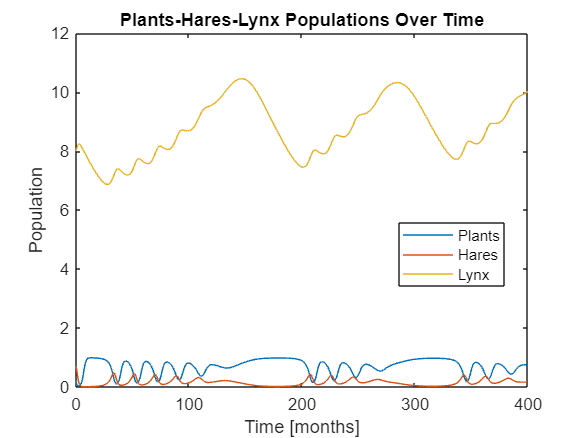

figure("Name",'Plants-Hares-Lynx')
plot(t,y)
title('Plants-Hares-Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plants','Hares','Lynxes','Location','Best')

**State space plot**

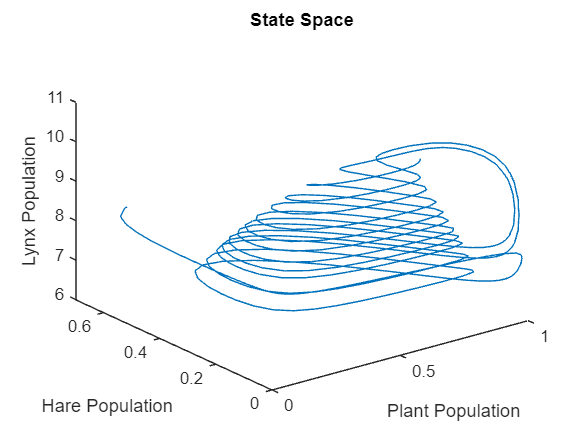

figure("Name",'State Space')
plot3(y(:,1),y(:,2),y(:,3));
title('State Space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')

**Task 2: **Find parameter solutions for the following three scenarios

**Scenario 1:** The system exhibits stable oscillations with a periodicity of approximately 70 months.

**Scenario 2:** The lynx population goes extinct (population very close to zero) after a year, plants and hares stabilize within 120 months.

**Scenario 3:** The system shows chaotic behavior and the lynx population peaks twice within the 200-months period. What makes this behavior chaotic and not oscillating or random? Hint: Chaotic behavior is deterministic, sensitive to initial conditions, bounded and irregular.

function dydt = plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2)

dydt = zeros(3,1);

% y(1) is X, number of plants
% y(2) is Y, number of hares
% y(3) is Z, number of lynxes

dydt(1) = y(1)*(1-y(1)) - ((a1*y(1))/(1+b1*y(1)))*y(2); %Plants
dydt(2) = ((a1*y(1))/(1+b1*y(1)))*y(2)-d1*y(2)-(a2*y(2)/(1+b2*y(2)))*y(3); %Hares
dydt(3) = (a2*y(2)/(1+b2*y(2)))*y(3) - d2*y(3); %Lynxes

end